# Signals #3: discrete orthogonal transforms

## Vector and matrix orthogonality

One vector of $N$ signal samples $\mathbf{x}^T=[x_1, x_2, ..., x_N]$ is **orthogonal** to another vector of $N$ signal samples $\mathbf{y}^T=[y_1, y_2, ..., y_N]$ if the inner product $<.>$ of these two vectors is equal to zero $<\mathbf{x}, \mathbf{y} > = 0$ ("$^*$" - complex conjugation):

$<\mathbf{x},\mathbf{y}> = \sum_{n=1}^{N} x_n y_n^* = x_1y_1^*+x_2y_2^*+...+x_Ny_N^* $$=\left\lbrack \begin{array}{cccc}
y_1^*  & y_2^*  & \cdots  & y_N^* 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
\vdots \\
x_N 
\end{array}\right\rbrack$.

**Analyze the Matlab code**. Check orthgonality of three vectors `v1, v2, v3`. Rotate them all by the same angle (using rotation matrices) and check their ortgonality again. Define your own longer othogonal vectors with and without 0s.

% Orthogonal vectors (like in 3D x-y-z space)
v1 = [ 1 0 0 ]';     % Vector no. 1 - unitary vector of x axis
v2 = [ 0 1 0 ]';     % Vector no. 2 - unitary vector of y axis
v3 = [ 0 0 1 ]';     % Vector no. 1 - unitary vector of z axis
ortho12 = v2' * v1,  % check alternatives: v2'*v2, sum( v1.*conj(v2) ), dot( v1, v2 )

ortho12 = 0

**Orthogonal matrix** **A** consists of orthogonal columns (or rows):


$$\mathbf{A}=\left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & \cdots  & a_{1N} \\
a_{21}  & a_{22}  & \cdots  & a_{2N} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{N1}  & a_{N\;2}  & \cdots  & a_{N\;N} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\left\lbrack \begin{array}{c}
a_{11} \\
a_{21} \\
\vdots \\
a_{N1} 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
a_{12} \\
a_{22} \\
\vdots \\
a_{N\;2} 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
\vdots \\
\vdots \\
\vdots \\
\vdots 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
a_{1N} \\
a_{2N} \\
\vdots \\
a_{N\;N} 
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


A matrix is **orthonormal** if inner product of its each column/row vector with itself is equal to 1:


$$<\mathbf{v},\mathbf{v}> = \sum_{n=1}^{N} v_n v_n ^*= v_1v_1^*+v_2v_2^*+...+v_Nv_N^* =1$$


Inverse of an **orthonormal matri**x is equal to its transposition (columns $\rightarrow$ rows) and conjugation. Therefore:

$\mathbf{A}^{-1} \mathbf{A} =  \left(  \mathbf{A}^{*} \right)^{T} \mathbf{A} =$$\left\lbrack \begin{array}{cccc}
a_{11}^*  & a_{21}^*  & \cdots  & a_{N1}^* \\
a_{12}^*  & a_{22}^*  & \cdots  & a_{N1}^* \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{1N}^*  & a_{2N}^*  & \cdots  & a_{N1}^* 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & \cdots  & a_{1N} \\
a_{21}  & a_{22}  & \cdots  & a_{2N} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{N1}  & a_{N\;2}  & \cdots  & a_{N\;N} 
\end{array}\right\rbrack$$=$$\left\lbrack \begin{array}{cccc}
1 & 0 & \cdots  & 0\\
0 & 1 & \cdots  & 0\\
\vdots  & \vdots  & \ddots  & \vdots \\
0 & 0 & \cdots  & 0
\end{array}\right\rbrack$$= \mathbf{I}$.


$$\;\;\;\;\;\;\;\;\;\;\;\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{cccc}
a_{11}^*  & a_{21}^*  & \cdots  & a_{N1}^* 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cccc}
a_{12}^*  & a_{22}^*  & \cdots  & a_{N\;2}^* 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cccc}
\cdots  & \cdots  & \cdots  & \cdots 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cccc}
a_{1N}^*  & a_{2N}^*  & \cdots  & a_{N\;N}^* 
\end{array}\right\rbrack 
\end{array}\right\rbrack \;\ast \;\;\left\lbrack \begin{array}{cccc}
\left\lbrack \begin{array}{c}
a_{11} \\
a_{21} \\
\vdots \\
a_{N1} 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
a_{12} \\
a_{22} \\
\vdots \\
a_{N\;2} 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
\vdots \\
\vdots \\
\vdots \\
\vdots 
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
a_{1N} \\
a_{2N} \\
\vdots \\
a_{N\;N} 
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


**Run the Matlab code**. Define different bigger orthogonal matrices.

% Orthogonal matrices (like in 3D x-y-z space)
A = [ v1 v2 v3 ];    % orthogonal vectors in columns
ortho2 = A' * A,     % check the result: you should obtain diagonl matrix

ortho2 =      1     0     0
     0     1     0
     0     0     1


Typically matrices of discrete orthogonal transformations have  in their columns sines/cosines with increasing frequency of oscillation. For example the DCT-IV matrix is defined as follows:

$S[n,k]=\sqrt{\frac{2}{N}} \cos \left( \frac{\pi}{N} (k+0.5)(n+0.5) \right), \qquad k,n=0,1,2,...,N-1$.

where in columns $k$ are put different oscillatory reference signals and in rows $n$ we have consecutive samples of them.

**Analyze the Matlab code**. Check matrix of the DCT-IV transform. Add matrices of some other orthogonal transformations (find them in the Internet).

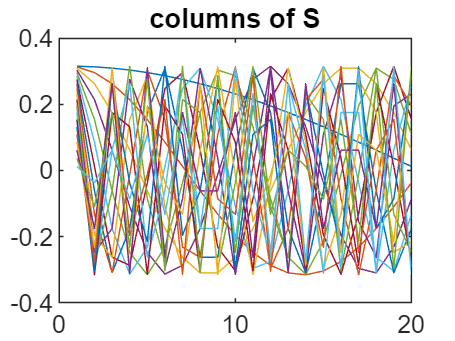

% Orthogonal matrix of the DCT-IV orthogonal transform  
N = 20;                                     % transformation order (square matrix size)
k = (0:N-1); n=(0:N-1);                     % columns=functions, rows=samples
S = sqrt(2/N)*cos(pi/N*(n'+1/2)*(k+1/2));   % orthogonal matrix of DCT-IV
plot(S); title('columns of S');             % shapes of all column vectors of A

S'*S,                                       % orthogonamal? 

ans =     1.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.0000    1.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    1.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.0000    1.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000   -0.0000    1.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000

## Discrete orthogonal transform concept

A pair of discrete orthogonal transformations, direct and inverse, using a pair of matrcies `A` and `S`, is defined as:

DIRECT (analysis):        $\mathbf{y=Ax=S}^{*T} \mathbf{x}
$, 

INVERSE (synthesis):   $\mathbf{\hat{x}=Sy=S(Ax)=SS}^{*T} \mathbf{x}=\mathbf{x}$

**1)** Elements of vector $\mathbf{y}$ are calculated as inner products of vector $\mathbf{x}$ with all rows of matrix $\mathbf{A}=\mathbf{S}^{*T}$. These inner products measure similarity existing between the vectors.

**2)** In the INVERSE transformation, vector $\mathbf{\hat{x}}$ is represented as a summations of columns of matrix $\mathbf{S}$, scaled by elements of vector $\mathbf{y}$. Thefore coefficients of $\mathbf{y}$ tells us how much each column of $\mathbf{S}$ is "present" in $\mathbf{\hat{x}}$.

## Signal analysis using direct DCT-IV

**Analyze the Matlab code**. Perform  DCT-IV transformation for different signals: observe their DCT "spectra", i.e. coefficients describing similarity between these signals and rows of matrix `A'`. 

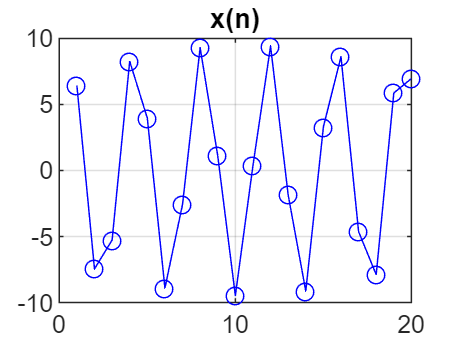

A = S';                                          % analysis matrix                                          
x1 = 10*S(:, 2);                                 % signal #1                 
x2 = 20*S(:, 5);                                 % signal #2
x3 = 30*sqrt(2/N)*cos(pi/N*(n'    +1/2)*(10.5+1/2) );  % signal #3
x4 = 30*sqrt(2/N)*cos(pi/N*(n'+N/2+1/2)*(10  +1/2) );  % signal #4
x5 = randn(1,N);                                 % signal #5
x = x4;                   % x1, x2, x3, x4, x1+x2, x1+x3, x1+x4 
figure; plot(x,'bo-'); title('x(n)'); grid;      % input

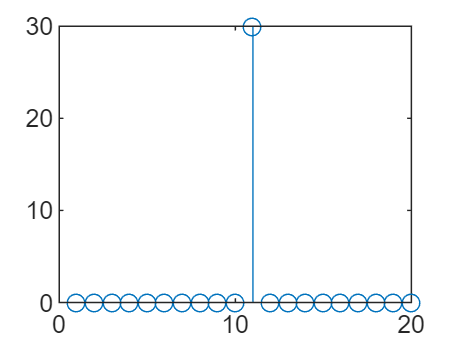

y = A*x;                     % signal analysis: finding similarity coeffs
figure; stem(y);             % displaying similarity coefficients

## Signal filtering using DCT-IV spectrum

Vector $\mathbf{y}$ tells us about "content" of a vector $\mathbf{x}$ as a summation of scaled columns of a matrix $\mathbf{S}$. Some components of $\mathbf{x}$ are desirable (they are part of our signal), some others are not (they are part of disturbances). By:

- zeroing elements of $\mathbf{y}$ associated with unwanted components of  $\mathbf{x}$,

- and performing the inverse transformation,

we are obtaining $\hat{\mathbf{x}}$ with unwated terms removed (denoised signal or separated signal part). To do such opperation efficiently, all signal components have to be compactly mapped to $\mathbf{y}$ coefficients.

**Analyze the Matlab code**. Turn on the filtering option. Try to remove from the signal some of its components. Check result.  

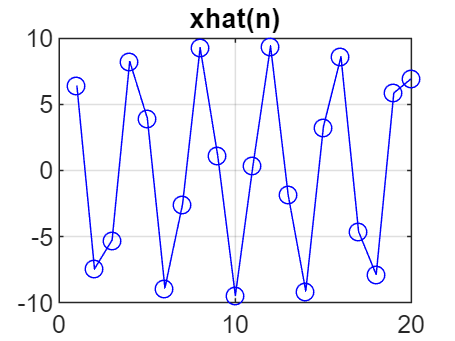

%y(5) = 0;                   % removing or not signal component x2 
xhat = S*y;                 % signal synthesis: summation of weighted elementary vectors
figure; plot(xhat,'bo-'); title('xhat(n)'); grid;  % output

error = max(abs(x-xhat)),    % signal reconstruction error

error = 2.1316e-14

**Record your own speech**. Calculate its DCT. Modify it, e.g. put zeros to some y(k). Perform inverse DCT. Listean to the synthesized speech.